#  KNAPSACK RECURSIVE

function maxVal = knapsack_recursive(W, weights, values, n)
    % Base case: no items or no capacity left
    if n == 0 || W == 0
        maxVal = 0;
        return;
    end

    % If weight of nth item is more than W, skip it
    if weights(n) > W
        maxVal = knapsack_recursive(W, weights, values, n-1);
    else
        % Include or exclude nth item
        include = values(n) + knapsack_recursive(W - weights(n), weights, values, n-1);
        exclude = knapsack_recursive(W, weights, values, n-1);
        maxVal = max(include, exclude);
    end
end

W=10;
weights=[20,2,4,5,7,12];
values=[13,23,4,6,14,11];
n=length(values);
maxVal = knapsack_recursive(W, weights, values, n);
fprintf('maximum value = %d',maxVal)

maximum value = 37

# KNAPSACK DYNAMIC

function maxVal = knapsack_dp(W, weights, values, n)
    K = zeros(n+1, W+1); % DP table

    for i = 1:n+1
        for w = 1:W+1
            if i == 1 || w == 1
                K(i, w) = 0;
            elseif weights(i-1) <= (w-1)
                K(i, w) = max(values(i-1) + K(i-1, w-weights(i-1)), K(i-1, w));
            else
                K(i, w) = K(i-1, w);
            end
        end
    end
    maxVal = K(n+1, W+1);
end

W=10;
weights=[20,2,4,5,7,12];
values=[13,23,4,6,14,11];
n=length(values);
 maxVal = knapsack_dp(W, weights, values, n);
 fprintf('maximum_value = %d\n',maxVal)

maximum_value = 37


# GRAPHICAL COMPARISON

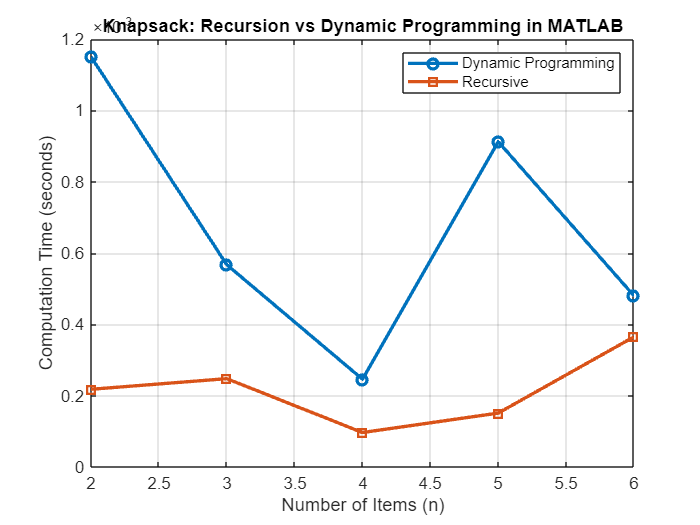

 max_n = 6;
dp_time = zeros(1, max_n);
rec_time = zeros(1, max_n);

for n = 2:max_n
    tic;
    knapsack_dp(W, weights(1:n), values(1:n), n);
    dp_time(n) = toc;

    tic;
    knapsack_recursive(W, weights(1:n), values(1:n), n);
    rec_time(n) = toc;
end

figure;
plot(2:max_n, dp_time(2:end), '-o', 'LineWidth', 2);
hold on;
plot(2:max_n, rec_time(2:end), '-s', 'LineWidth', 2);
xlabel('Number of Items (n)');
ylabel('Computation Time (seconds)');
legend('Dynamic Programming', 'Recursive');
title('Knapsack: Recursion vs Dynamic Programming in MATLAB');
grid on;